# 微分の定義(2.アニメーション)

ワークスペース変数を消去，コマンドウィンドウを初期化，すべてのFigureウィンドウを閉じる．

clear;clc;close all;
syms f t
f=t^2

$$f = t^{2}$$

dfdt=diff(f,t)

$$dfdt = 2\,t$$

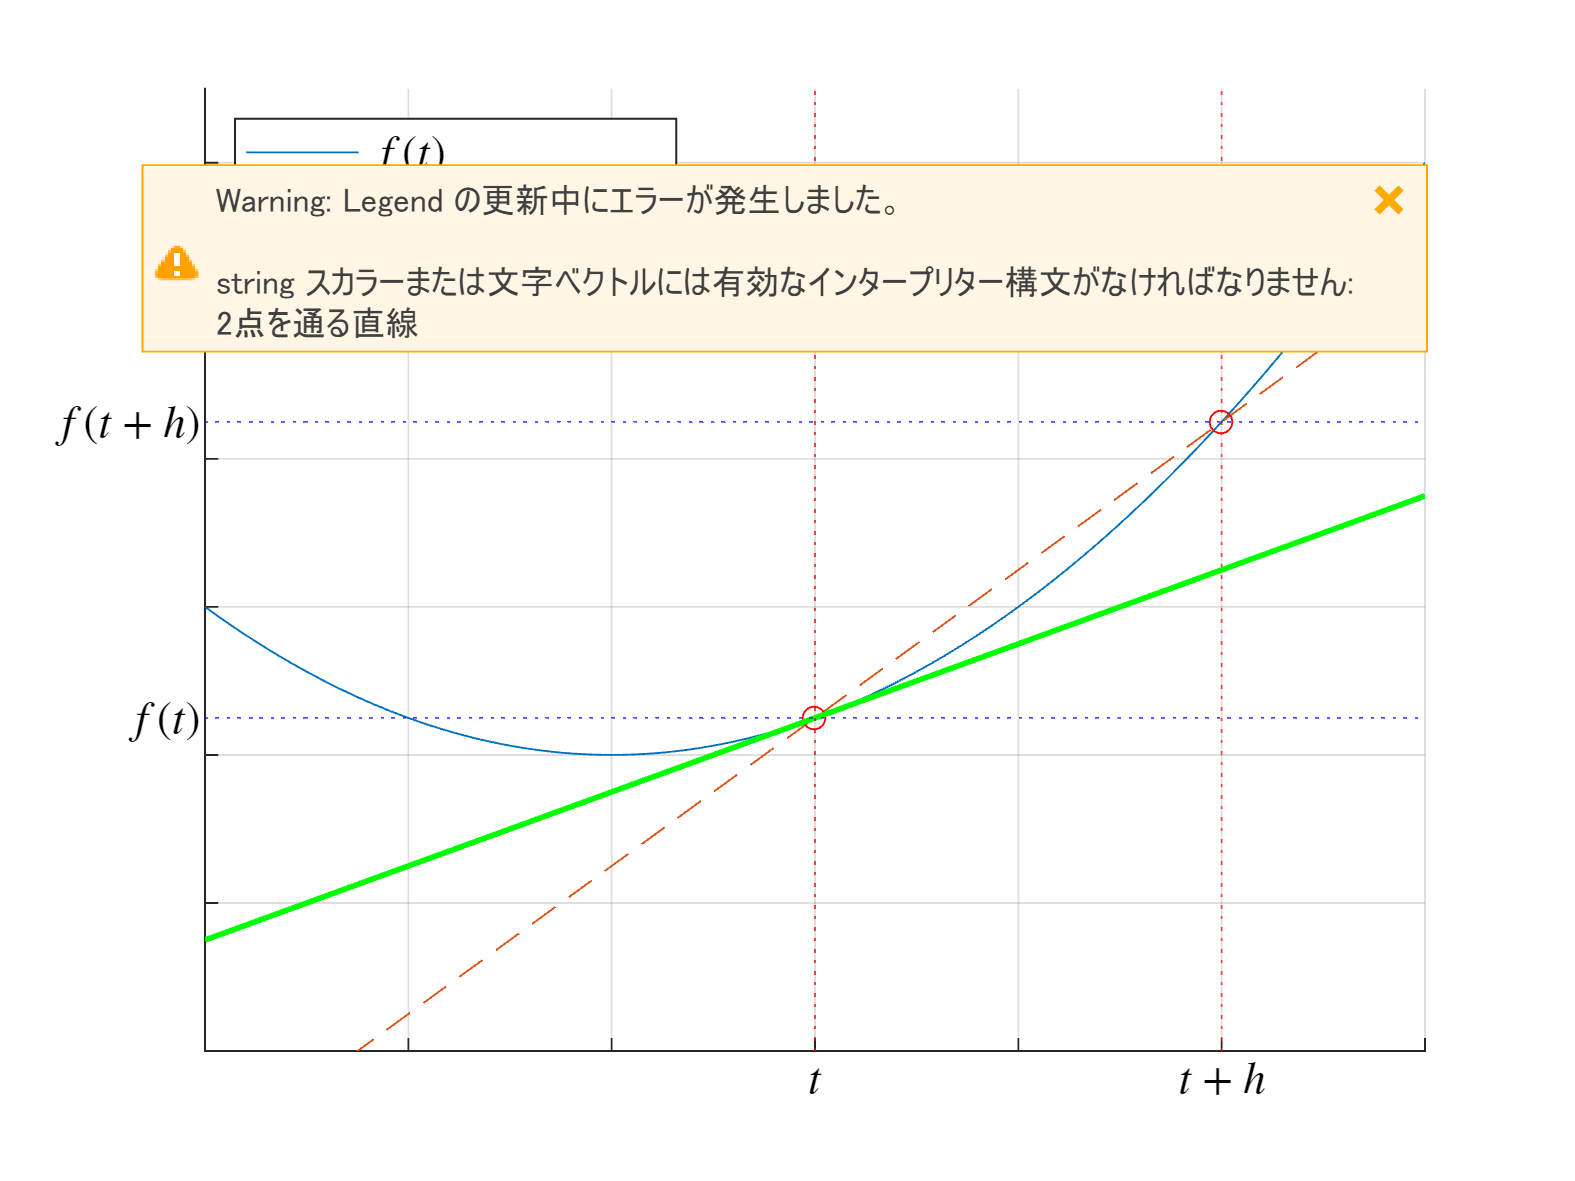

tVal=linspace(-1,2,100);

delta_t=1;
t1=0.5;t2=t1+delta_t;
f1=subs(f,t1);f2=subs(f,t2);
a=(f2-f1)/(t2-t1);
y=a*(tVal-t1)+f1;
y2=subs(dfdt,t1)*(tVal-t1)+f1;

fVal=subs(f,t,tVal);
figure
grid on;hold on;
set(gca,'fontname','メイリオ');
hl(1)=plot(tVal, fVal);
axis([-1 2 -2 4.5]);
hl(2)=plot(tVal,y,'--');hp(1)=plot(t1,f1,'ro');hp(2)=plot(t2,f2,'ro');
hl(3)=plot(tVal,y2,'g-','LineWidth',1.5);
hxl=xline([t1,t2],'r:');
hyl=yline(double([f1,f2]),'b:');
xticklabels([]);
yticklabels([]);
htx(2)=text(t2,-2,'$t+h$','Interpreter','latex','FontSize',12,...
    'HorizontalAlignment','center','VerticalAlignment','top');
htx(1)=text(t1,-2,'$t$','Interpreter','latex','FontSize',12,...
    'HorizontalAlignment','center','VerticalAlignment','top');
hty(2)=text(-1,f2,'$f(t+h)$','Interpreter','latex','FontSize',12,...
    'HorizontalAlignment','right','VerticalAlignment','middle');
hty(1)=text(-1,f1,'$f(t)$','Interpreter','latex','FontSize',12,...
    'HorizontalAlignment','right','VerticalAlignment','middle');
legend(hl,{'$f(t)$','2点を通る直線','接線'},'Interpreter','latex','FontName','メイリオ','FontSize',12,...
    'Location','northwest');

for delta_t=[1:-0.01:0.01, 0.01:0.01:1]
    t2=t1+delta_t;
    f1=subs(f,t1);f2=subs(f,t2);
    a=(f2-f1)/(t2-t1);
    y=a*(tVal-t1)+f1;
    y2=subs(dfdt,t1)*(tVal-t1)+f1;

    hl(2).YData=y;
    hp(2).XData=t2;hp(2).YData=f2;
    htx(2).Position(1)=t2;
    hty(2).Position(2)=f2;
    hxl(2).Value=t2;
    hyl(2).Value=double(f2);
    drawnow;
    pause(0.01);
end